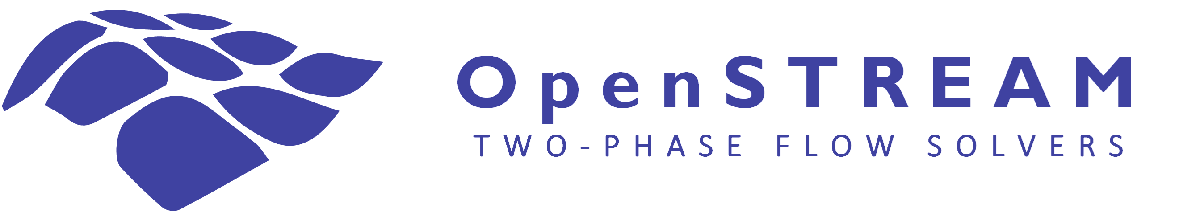

# Tutorial #2: Mixture solver

## Introduction

In this tutorial, you will learn how to use the OpenSTREAM [mixture solver](https://openstream-solvers.github.io/openstream/Packages/Solvers-Mixture.html), with examples demonstrating various capabilities.

The selected geometry consist of a 3.5 m uniformly heated vertical tube with an inner diameter of 8.8 mm, followed by a 2 m adiabatic section (of same diameter). The flow enters slightly subcooled, transitions to annular two-phase flow around 0.7 m, and reaches the critical boiling transition (film dryout) at the end of the heated section. In the adiabatic region, droplets deposit on the wall, regenerating the liquid film at the wall and leading to a fully developed annular flow.

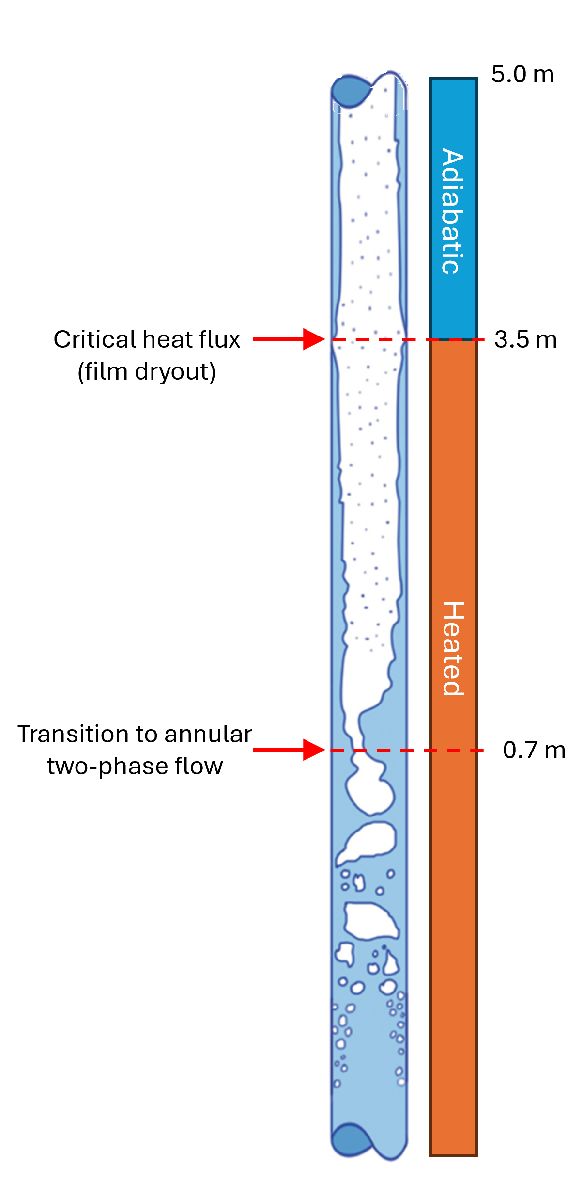

% Clear existing variables from workspace
clearvars

Before starting this tutorial, make sure OpenSTREAM is included in your MATLAB search path. If you are running the tutorial directly from the `tutorials` folder, you can add OpenSTREAM like this:

% Add path to OpenSTREAM
osp = './..';                      % When running from the tutorials folder
addpath(osp);

## Input files

All the input files you will need for this tutorial are already provided in the `openstream/inputs/` folder.

We first start by adding the inputs and solver packages to the import list. 

% Import the inputs and solvers packages
import Inputs.*
import Solvers.*

We then add the mixture solver module to the import list. 

% Import the mixture solver module
import Solvers.Mixture.*

The mixture solver module in OpenSTREAM provides classes and tools for simulating two-phase flows using a [mixture](https://openstream-solvers.github.io/openstream/Guides/theory/Mixture_Model_Theory.html) approach.

We can examine the physical model inputs by opening the `model.inp` file or using the command below, then scroll to locate the `ID` entries labeled `TUTORIAL2*`.

type('../inputs/models.inp')

These indicate that the simulations will use 100 nodes and that water is the working fluid. Models not specificed are set to their default values by the code. Default models are listed [here](https://openstream-solvers.github.io/openstream/Packages/Inputs.html#Inputs.Model) and are set within the `Inputs.Model` class definition file.

In this tutorial , the following model sets will be used:

- `TUTORIAL2A` does not specified any model, hence an homogeneous equilibrium model (HEM) is assumed.

- `TUTORIAL2B` selects a slip void model with a slip ratio of 2

- `TUTORIAL2C` selects a drift flux model (`BESTION`)

- `TUTORIAL2D` selects a drift flux model (`BESTION`) and thermal non-equilibrium model for subcooled boiling (`SAHAZUBER`)

- `TUTORIAL2E` selects a drift flux model (`BESTION`) and generic thermal non-equilibrium model based on a relaxation approach (`HRM`)

We can examine the numerical option inputs by opening the `options.inp` file or using the command below, then scroll to locate the `ID` entry labeled `DEFAULT`.

type('../inputs/options.inp')

Note that no specific options have been defined, i.e., defaults setting are used for the simulations. Default options are listed [here](https://openstream-solvers.github.io/openstream/Packages/Inputs.html#Inputs.Options) and are set within the `Inputs.Options` class definition file.

We can examine the geometry inputs by opening the `geom.inp` file or using the command below, then scroll to locate the `ID` entry labeled `TUTORIAL1`.

type('../inputs/geom.inp')

All inputs are specified in SI units and required except for `ANGLE`, which defaults to 0, indicating a vertical (upward) test section. The separate specification of `AREA` and `PERIM` allows to define test sections of arbitrary shape. In this case, the area and perimeter corresponding to a circular test section with a diameter 8.8 mm were specified.

Finally, we can examine the boundary conditions by opening the boundary conditions file or using the command below.

type('../inputs/tutorial1.inp')

Defining a single time step indicates that the simulation is steady-state. The axial power distribution is specified using two arrays: `WMESH` for node size and `WPOWER` for corresponding wall heat flux. In this case, the configuration represents a 3.5 m uniformly heated section followed by a 2 m adiabatic section.

All inputs are specified in SI units and required except for `WMESH` and `WPOWER`. If they are omitted, the test section is assumed to be uniformly heated by default.

## Homogeneous Equilibrium Model (HEM)

In this section, we will walk through how to set up and run the mixture solver using the simplest set of physical models available.

By default, the physical models in the mixture solver are consistent with the Homogeneous Equilibrium Model (HEM). That is, hydrodynamic and thermal equilibrium is assumed along with no slip between the phases.

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet` as shown below. Since each file can include various set of inputs (several geometries, etc.), the `ID`s corresponding to the relevant sets must be indicated. New user-specific files can be created and the paths can be modified by the user, based on the specific working directory and file locations.

The models and options parameters not specified in the input files are set to their default values listed [here](https://openstream-solvers.github.io/openstream/Packages/Inputs.html).

% Turn off warnings during input setup
%warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSetA = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2A', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
%warning on

Note:

- Turning on the warning will print the set default values to the prompt.

- LOGMODE can be set to 'LOGTOFILEONLY' to suppress (almost) all print outputs when running OpenSTREAM.

A mixture solver object, `mixSolverA`, is created from `inputSetA` (which contains all information related to geometry, boundary conditions, physical models and options).

% Create the mixture solver object
mixSolverA = MixtureSolver(inputSetA);

To solve the flow fields, simply call the `solve` method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolverA.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If steady-state convergence is reached, it prints a summary of the time step convergence.

The mixture solver class includes built-in plotting methods to help visualize the results. Not indicating any argument (`mixSolver.plotz()`) will generate figures for most relevant parameters. Various name-value arguments are available, such as `display` to select the parameter(s) to be plotted. Further information how to use the plotz method can be found [here](https://openstream-solvers.github.io/openstream/Packages/Solvers-Mixture.html#Solvers.Mixture.MixtureSolver.MixtureSolver.plotz).

We start by plotting the axial distribution of wall heat flux along the test section.

% Plot the axial distribution of heat flux
mixSolverA.plotz('display','HFLUX');

The wall heat flux is imposed by the `WMESH` and `WPOWER` inputs in the boundary conditions input file. Here we verify that uniform power is applied along the first 3.5 m, followed by a 2 m long adiabatic region.

We can then plot the axial distributions of mixture and phase mass flow rates.

% Plot the axial distribution of mass flow rates
mixSolverA.plotz('display','W');

Vapor generation begins near the inlet of the test section as the mixture reaches saturation. From there, vapor mass increases linearly along the heated length due to the uniform heat flux, and then remains constant throughout the adiabatic section. This is a typical behavior expected for a homogeneous equilibrium model (HEM).

Finally, we plot the axial distributions of vapor volumetric (void) and mass (quality) ratios.

% Plot the axial distributions of vapor ratio
mixSolverA.plotz('display','VR');

The figure confirms that the mixture becomes saturated ($x_\mathrm{eq} \geq 0$) as the steam mass (and void fraction) starts increasing.

Results can be saved if desired.

% Save the solver object
mixSolverA.save('name','mixSolverA','showpath',false)

The solver object can be retrieved later by using the `load` command.

## Non-homogeneous models

In this section, two non-homogeneous models are demonstrated where the phases have different velocities. This is achieved by calculating the void fraction based either on the slip void model or a drift flux void model, instead of the homogeneous void model.

### Slip void model

In this section, we will walk through how to set up and run the mixture solver using a simple slip void model and a phase velocity ratio set to 2.

The only difference with the previous case is that input `VOID` is set to `SLIP` and input `SLIP` is set to `2` in the model  set.

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet`. The models `ID` corresponding to the void slip model (`TUTORIAL2B`) is indicated.

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSetB = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2B', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

A mixture solver object, `mixSolverB`, is created from `inputSetB`.

% Create the mixture solver object
mixSolverB = MixtureSolver(inputSetB);

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolverB.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If steady-state convergence is reached, it prints a summary of the time step convergence.

We plot the axial distributions of vapor volumetric (void) and mass (quality) ratios.

% Plot the axial distributions of vapor ratio
mixSolverB.plotz('display','VR');

While the quality is the same as in the previous simulation (thermodynamic equilibrium assumption), the void is slightly lower, characteristic of the imposed velocity slip between the vapor and liquid phases.

This is verified by plotting the axial distributions of phase velocity.

% Plot the axial distributions of phase velocity
mixSolverB.plotz('display','U');

The calculated vapor velocity is observed to be twice higher than the liquid velocity, as specified by the `SLIP` void model.

### Drift flux void model

In this section, we will walk through how to set up and run the mixture solver using a drift flux void model.

The only difference with the previous case is that input `VOID` is set to `BESTION` in the model set. This model is one of several drift flux void model available in the literature, which has the merit to be simple and accurate for many applications.

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet`. The models `ID` corresponding to the Bestion drift flux model (`TUTORIAL2C`) is indicated.

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSetC = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2C', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

The mixture solver object, `mixSolverC`, is created from `inputSetC`.

% Create the mixture solver object
mixSolverC = MixtureSolver(inputSetC);

To solve the flow fields, simply call the `solve` method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolverC.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If steady-state convergence is reached, it prints a summary of the time step convergence.

We plot the axial distributions of vapor volumetric (void) and mass (quality) ratios.

% Plot the axial distributions of vapor ratio
mixSolverC.plotz('display','VR');

While the quality is the same as in the previous simulation (thermodynamic equilibrium assumption), the void is slightly different due to different and varying velocity differences between the phase along the channel imposed by the drift flux model.

This is verified by plotting the axial distributions of phase velocity.

% Plot the axial distributions of phase velocity
mixSolverC.plotz('display','U');

The calculated vapor velocity is observed to be higher than the liquid velocity (with a non-constant slip ratio), as specified by the `BESTION` drift flux void model.

## Thermal non-equilibrium models

In this section, two thermal non-equilibrium models are demonstrated where the phases have different temperatures. This is achieved by calculating the vapor mass quality based either on an empirical model or a physical model representative of interfacial mass and heat transfer, instead of the thermal equilibrium assumption.

### Empirical model

In this section, we will walk through how to set up and run the mixture solver using an empirical thermal non-equilibrium model to simulate subcooled boiling.

The only difference with the previous case is that input `THERMALNONEQ` is set to `SAHAZUBER` in the models file.

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet`. The models `ID` corresponding to the Saha-Zuber subcooled boiling model (`TUTORIAL2D`) is indicated.

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSetD = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2D', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

The mixture solver object, `mixSolverD`, is created from `inputSetD`.

% Create the mixture solver object
mixSolverD = MixtureSolver(inputSetD);

To solve the flow fields, simply call the `solve` method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolverD.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If steady-state convergence is reached, it prints a summary of the time step convergence.

We plot the axial distributions of vapor volumetric (void) and mass (quality) ratios.

% Plot the axial distribution of vapor ratios
mixSolverD.plotz('display','VR');

The vapor mass quality begins to increase near the inlet, even though the equilibrium thermodynamic quality remains negative. Consequently, the void fraction also increases in that region. This behavior is characteristic of subcooled boiling, as captured by the Saha-Zuber model.

### Homogeneous Relaxation Model (HRM)

In this section, we will walk through how to set up and run the mixture solver using a physical and generic thermal non-equilibrium model that can simulate both subcooled boiling and post-boiling transition (i.e., superheated vapor).

The only difference with the previous case is that input `THERMALNONEQ` is set to `HRM` in the models file. This Homogeneous Relaxation Model (HRM) is based on two additional conservation equations for the vapor phase (mass and energy) allowing to physically describe thermal non-equilibrium exchanges (evaporation and condensation) across the interface. In this tutorial, the time relaxation model is set to its default value.

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet`. The models `ID` corresponding to the homogeneous relaxation model (`TUTORIAL2E`) is indicated.

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSetE = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2E', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

The mixture solver object, `mixSolverE`, is created from `inputSetE`.

% Create the mixture solver object
mixSolverE = MixtureSolver(inputSetE);

To solve the flow fields, simply call the `solve` method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolverE.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If steady-state convergence is reached, it prints a summary of the time step convergence.

We plot the axial distributions of vapor volumetric (void) and mass (quality) ratios.

% Plot the axial distribution of vapor ratios
mixSolverE.plotz('display','VR');

The vapor mass quality begins to increase near the inlet, even though the equilibrium thermodynamic quality remains negative. Consequently, the void fraction also increases in that region. This behavior is characteristic of subcooled boiling, as captured by the HRM model.

A future tutorial will describe in details the features and capabilities of the Homogeneous Relaxation Model, including the simulation of thermal non-equilibrium in post-boiling transition.

## Pressure drop models

In this section, the axial pressure drop  models and simulation results are discussed. The axial pressure drop components (gravitational, wall shear and accelerations) are resolved from the mixture momentum conservation equation (which solves for the total pressure drop). The code saves the pressure drop components individually for easy retrieval.

### Axial pressure drop components

Using an already solved mixture solver object (`mixSolverD`, based on Saha-Zuber subcooled boiling model), the cumulative pressure drop components can be plotted as follows.

% Plot the axial distribution of pressure drop contributors
mixSolverD.plotz('display','DP');

The references pressure is based on the inlet and, while the cumulative pressure drop is negative along the axial lengths, it is represented as a positive value on the figure.

For this case, both the local and temporal acceleration pressure drop components are 0. This is expected for a steady-state case in a channel with no obstruction. In addition, the spacial acceleration component remains constant along the adiabatic length, as expected.

As can be observed from the figure for two-phase convective boiling at high mass flux, the pressure drop is dominated by the wall friction, followed by the spatial acceleration (from boiling and related density decrease).

### Wall friction

The wall fraction pressure drop is due to the shear of the flowing mixture on the channel boundaries. For one-dimensional analysis, correlations are typically used in term of a wall friction factor, from which the wall shear and wall friction pressure drop are derived. For two-phase flow applications, a wall friction two-phase multiplier is used to account for the increase of wall shear. Both wall friction factor and wall friction two-phase multiplier are generally derived from experimental data. A few typical models are implemented in OpenSTREAM. In this section, a Blasius type wall friction factor is set, along with the EPRI wall friction two-phase multiplier.

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet`. The models `ID` (`TUTORIAL2F`) corresponding to a Blasius type wall friction model ($0.2/Re^{0.2}$) along with the EPRI two-phase flow multiplier is indicated.

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSetF = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2F', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

The mixture solver object, `mixSolverF`, is created from `inputSetF`.

% Create the mixture solver object
mixSolverF = MixtureSolver(inputSetF);

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolverF.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If steady-state convergence is reached, it prints a summary of the time step convergence.

We plot the axial cumulative distributions of pressure drop components.

% Plot the axial distribution of pressure drop contributors
mixSolverF.plotz('display','DP');

The change in wall friction model (from default) leads to an increase in wall friction, and hence total pressure drop.

### Singular pressure losses

In an obstructed channel (e.g., due to a structural component, a flow mixer, a valve, etc.), the pressure drop can increase significantly across the obstruction. This is represented in the code by a singular pressure drop scaled with a pressure drop coefficient. For two-phase flow applications, a local two-phase multiplier is used to account for the increase of pressure drop. Both pressure drop coefficient and local pressure drop two-phase multiplier are generally derived from experimental data. A few typical models are implemented in OpenSTREAM. In this section, constant local pressure drop coefficients are set, along with the homogeneous local pressure drop two-phase multiplier.

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet`. The models `ID` (`TUTORIAL2G`) corresponding to channel with 5 obstructions (at 1, 2, 3, 4 and 5 m) of loss coefficient 0.5 is indicated. The homogeneous model for the two-phase local pressure drop multiplier is selected.

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSetG = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2G', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

The mixture solver object, `mixSolverG`, is created from `inputSetG`.

% Create the mixture solver object
mixSolverG = MixtureSolver(inputSetG);

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolverG.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If steady-state convergence is reached, it prints a summary of the time step convergence.

We plot the axial cumulative distributions of pressure drop components.

% Plot the axial distribution of pressure drop contributors
mixSolverG.plotz('display','DP');

The addition of local perturbations (with associated pressure loss coefficients) leads to clear local increases in pressure drop, and hence total pressure drop.

## Transient

In this section a transient case is simulated, representative of a power decrease (by half of the nominal power over 1 sec). This example demonstrates the dynamic capabilities of OpenSTREAM for a simple case.

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet`.

The transient boundary conditions are specified in the `tutorial2_transient.inp` file. We can examine the file by using the command below.

type('../inputs/tutorial2_transient.inp')

The format of the file is similar to setting a steady-state case, except that several set of inputs are provided at various (arbitrary) time, defining the transient. Any input parameter in the boundary conditons file can vary with time, that is:

- System pressure

- Inlet enthalpy

- Inlet mass flow

- Power

- Axial power distribution

In this tutorial, only the power is varied.

Regarding the model file, the models `ID` previously used to set the Bestion drift flux void model and the Saha-Zuber subcooled boiling model (`TUTORIAL2D`) is indicated.

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSetH = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2D', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/tutorial2_transient.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

The mixture solver object, `mixSolverH`, is created from `inputSetH`.

% Create the mixture solver object
mixSolverH = MixtureSolver(inputSetH);

To solve the flow fields, simply call the solve method (no input arguments are needed). Initially, the solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state. After steady-state convergence, the solver proceeds to simulate the transient scenario specified in the boundary conditions file.

% Solve the flow fields
mixSolverH.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). During the pseudo-transient simulation, it then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If steady-state convergence is reached, it prints a summary of the time step convergence.

We plot the axial distributions of heat flux (a boundary conditions) and of vapor volumetric (void) and mass (quality) ratios.

% Plot the axial distribution of heat fluc and vapor ratios
mixSolverH.plotz('display',{'HFLUX','VR'},'arrangement','horizontal','resize',1);

The initial solution is the same as the steady-state solution of case 2D, as expected. The `plotz` method of the `mixtureSolver` has the capability of showing the axial distribution of the selected parameters for each time step and play the entire transient (once or in a loop) by using the command button on the bottom left of the figure window. A video of the transient can be generated by using the animation drop dow menu

.